# MRI Reconstruction Demo Script

                                                               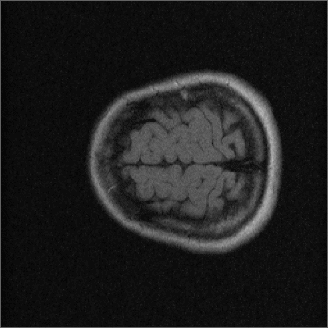

This demo script showcases the process of MRI reconstruction using k-space data. It is designed to run efficiently on both GPU and CPU, providing three types of visualizations: Volume Rendering, Cinematic Rendering, and Slice Viewer. Additionally, the script generates CUDA code for all three approaches, ensuring high performance and flexibility.

## Key Features:

- MRI Reconstruction: Utilizes k-space data to reconstruct MR images and following approaches

- MRI Reconstruction Using IFFT and Root Sum Squares

- Compressed Sensing (CS)

- MRI Reconstruction Using Deep Learning with U-Net

         2. Multi-platform Execution: Runs on both GPU and CPU.

         3. Visualization Options: Offers Volume Rendering, Cinematic Rendering, and Slice Viewer for comprehensive image analysis. 

         4. CUDA Code Generation: Generates CUDA code to optimize the reconstruction process

**Load MRI k-space Data**: First, we load the k-space data from an HDF5 file. The `h5read` function is used to read the specified dataset from the file.


fileName ="2022061003_T101.h5";
datasetPath = '/kspace';
data =h5read(fileName,datasetPath)

data = struct with fields:
    r: [256x256x4x18 single]
    i: [256x256x4x18 single]


**Set Acceleration Factor**: Define the acceleration factor for undersampling the k-space data. This factor determines the level of undersampling applied during the reconstruction process. *(Applicable only for Compressed Sense (CS) and Deep Learning (DL) methods)*

%Accleration factor
factor =2

factor = 2

**Perform MRI Reconstruction**: Use the appropriate method from dropdown to perform MRI reconstruction using the loaded k-space data and the specified acceleration factor.

%MRI Reconstruction approach
reconImage = reconstructionWithIFFT(data);

# Visualization of MRI Reconstruction

Visualizing MRI reconstruction results is crucial for analyzing and interpreting the data. Various visualization techniques can be employed to view and understand the reconstructed images effectively.

**Medical volume datastore **

The [`medicalVolume`](https://www.mathworks.com/help/medical-imaging/ref/medicalvolume.html) function in MATLAB is used to create a medical volume object from image data. This object encapsulates the voxel data and associated metadata, such as the volume's geometry and patient coordinate system

R = medicalref3d(size(reconImage));
medVolReconImage =medicalVolume(reconImage,R);
medVolReconImage.VolumeGeometry.PatientCoordinateSystem ="LPS+";
voxInfo =medVolReconImage.Voxels;
min_val = min(voxInfo(:));
max_val = max(voxInfo(:));
normalized_data = (voxInfo(:) - min_val) / (max_val - min_val);

normalized_data =reshape(normalized_data,[256 256 18]);
newMedVol= medicalVolume(normalized_data,medVolReconImage.VolumeGeometry);


## Visualization Methods

#### Slice View:

Displays individual slices of the 3D reconstructed image, allowing detailed examination of each slice.

sliceViewer(newMedVol,Parent=figure)

### Volume Rendering

Provides a 3D visualization of the reconstructed image using cinematic rendering, enhancing the depth and detail of the image.

c =bone(20);
volshow(newMedVol,RenderingStyle="CinematicRendering",Colormap=c)

#### Montage View

Creates a montage of slices from the 3D reconstructed image, offering a comprehensive overview of the entire volume.

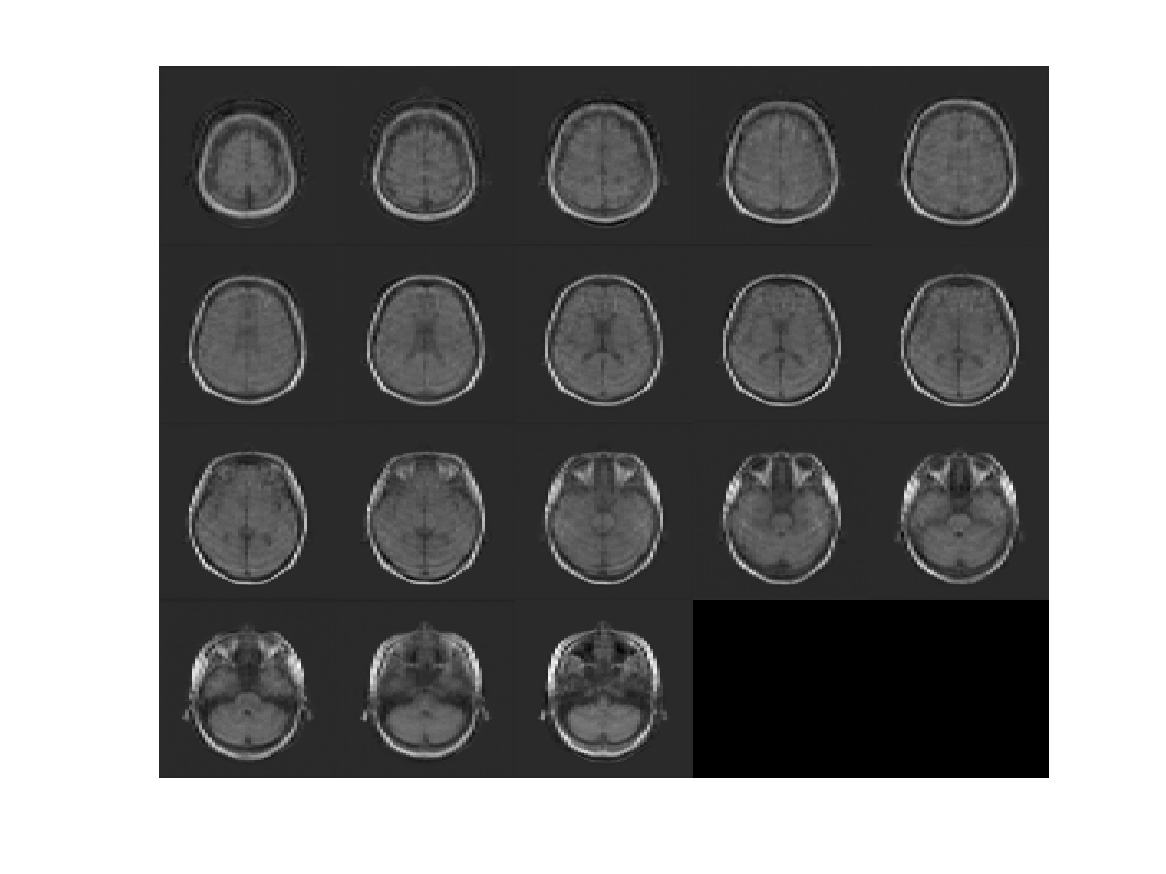

montage(newMedVol)

## GPU Code Generation

In this section, we will demonstrate how to generate GPU code for the three approaches using respective functions in the drop-down list using MATLAB's GPU Coder. This allows us to leverage the computational power of GPUs to accelerate the processing of k-space data.

**Steps:**

**Configuration for GPU Code Generation**: First, we create a configuration object for generating MEX functions that can run on the GPU.

cfg = coder.gpuConfig('mex');

**Generate GPU Code**: We use the `codegen` command to generate the GPU code for the selected function from drop-down. The `-config cfg` option specifies the configuration object, and the `-args {data}` option provides the input arguments for the function.

*Please note for compressed sense and Deep learning approaches : the acceleration factor is selected by default 2. You can change it as per your use.*

codegen -config cfg processKspaceCS -args {data}


Warning in ==> processKspaceCS Line: 64 Column: 49
Code generation successful (with warnings): View report



**Execute the Generated MEX Function**: After generating the GPU code, we can call the MEX function to process the k-space data.

MR_Image = processKspaceCS_mex(data);

**Visualize the Reconstructed Images**: Finally, we visualize the reconstructed frames using a loop to display each frame sequentially.

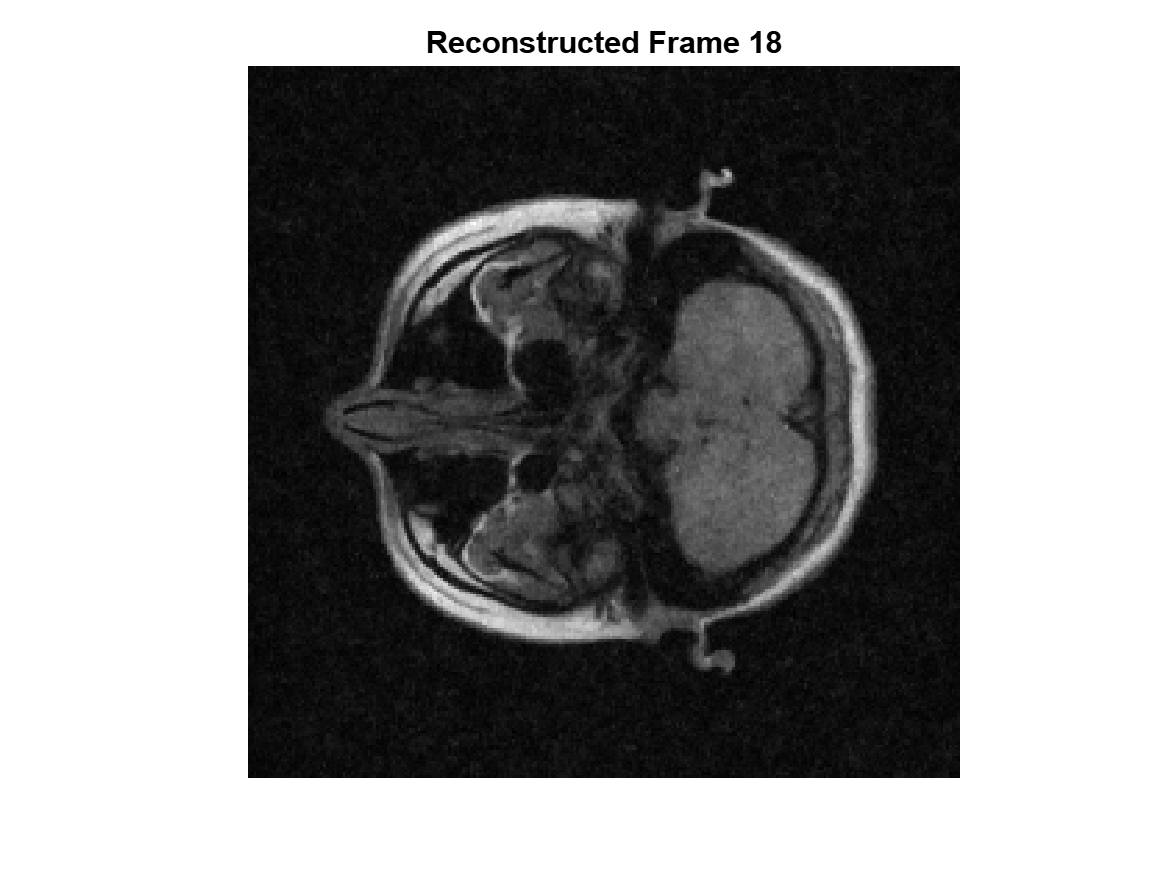

figure;
for frame = 1:18
    imshow(abs(MR_Image(:,:,frame)), []);
    title(sprintf('Reconstructed Frame %d', frame));
    pause(0.5); % Pause for visualization
end